clc; % czysci command window
clear; %czysci zmienne
close; %zamyka wszystkie okna

## Geometria i geometria odwrotna

Wykres wydłużenia siłownika w funkcji kąta wychylenia steru

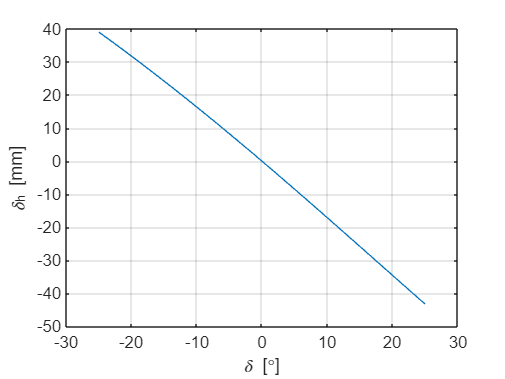

y_max = 100;
L = 180;
R=100;
Y=180;
alpha=asin(R/(2*L));
alpha_prim=pi/2 - alpha;

delta=-25:0.1:25;

delta_h = -(Y-sqrt(L^2+R^2-2*L*R*cos(alpha_prim-delta*pi/180)));

figure;
plot(delta,delta_h);
grid on
xlabel('\delta [\circ]');
ylabel('\delta_h [mm]');
grid on
hold on

## Dynamika układu

Zależność siły wzdłużnej w siłowniku od kąta wychylenia steru i momentu aerodynamicznego

v_dzwieku = 340.3;
Ma= 0.3;
v_lotu = v_dzwieku*Ma;
c = 2.37;
rho = 1.2255;
b = 12.45;
wsp1 = 0.5*rho * c^2 * b;
V = (0.1*v_dzwieku:10:0.5*v_dzwieku)';


delta_dyn = [-25, -20, -10, 0, 10, 20, 25];
delta_dyn = deg2rad(delta_dyn);
cm_h = [-0.033139, -0.027379, -0.017291, -0.000038, 0.017291, 0.027379, 0.033139];
M_h = wsp1*cm_h;

    delta_h_dyn = -(Y-sqrt(L^2+R^2-2*L*R.*cos(alpha_prim-delta_dyn)));
    beta = acos((R^2 +delta_h_dyn.*(delta_h_dyn+2*L))./(2*R*(L+delta_h_dyn))) - pi/2;
    R_B = M_h./(R*cos(beta))

R_B =    -0.0175   -0.0138   -0.0081   -0.0000    0.0075    0.0117    0.0143


    
Q = V.^2*R_B

Q =   -20.2476  -16.0177   -9.4137   -0.0196    8.6504   13.5980   16.5948
  -33.8959  -26.8148  -15.7593   -0.0329   14.4814   22.7640   27.7809
  -51.0410  -40.3782  -23.7306   -0.0495   21.8064   34.2785   41.8329
  -71.6831  -56.7080  -33.3277   -0.0695   30.6254   48.1414   58.7510
  -95.8220  -75.8041  -44.5506   -0.0929   40.9383   64.3528   78.5351
 -123.4577  -97.6666  -57.3994   -0.1197   52.7452   82.9126  101.1853
 -154.5904 -122.2955  -71.8739   -0.1499   66.0461  103.8209  126.7014
 -189.2199 -149.6906  -87.9742   -0.1834   80.8410  127.0777  155.0836
 -227.3462 -179.8522 -105.7004   -0.2204   97.1298  152.6829  186.3317
 -268.9695 -212.7801 -125.0523   -0.2607  114.9127  180.6365  220.4459


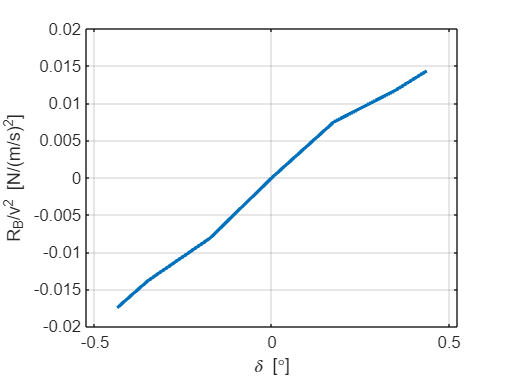



figure;
plot(delta_dyn,R_B,'LineWidth',2);
grid on
xlabel('\delta [\circ]');
ylabel('R_B/v^2 [N/(m/s)^2]');
axis([-pi/6 pi/6 -0.02 0.02])
grid on
hold on